# Inverse Kinematics

In this section, we'll see how to calculate the **Inverse Kinematics of a Robot**, i.e. to find the specific joint angles to get the robot's end effector to a certain place using the Geometric Approach.

## The Inverse Kinematics problem for a 6 DoF Robot

Consider a typical 6 DoF Robot, similar to what we have been looking at.

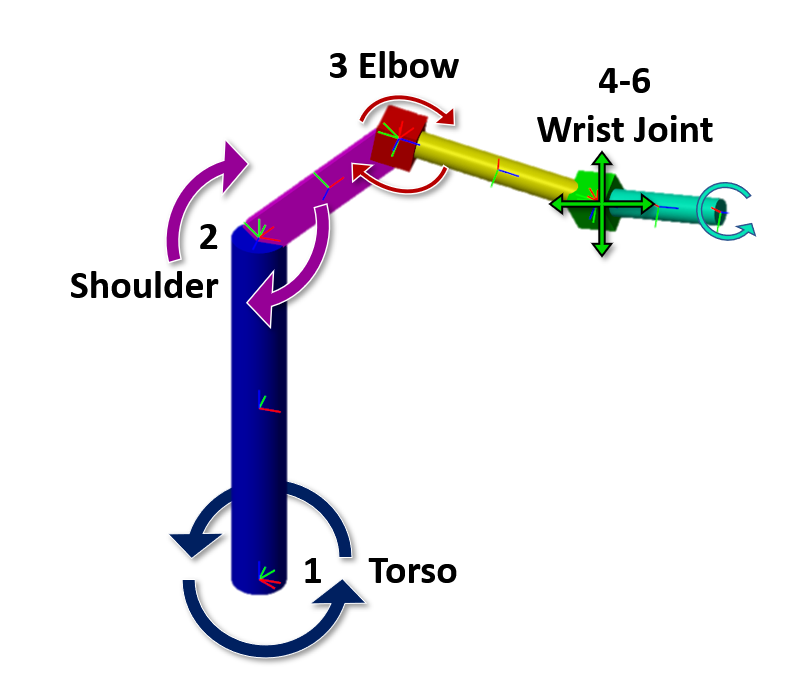

This Robot has:

- A 'Torso' revolute joint (1) for angular rotation (horizontal movement)

- 'Shoulder' (2) and 'Elbow' (3) revolute joints for vertical movement

- A 3 DoF wrist joint (4-6) which can move the end effector to any orientation and rotation within the reachable distance. This is usually accomplished by having 3 revolute joints acting about the same point: 2 for the wrist pitch/yaw motions and 1 for the roll or 'twist' motion.

### Challenge

The inverse kinematics problem for 6 degrees-of-freedom can become very complex because there are many possible solutions for how to reach a given point. For example, there are 4 possible solutions just for Joints 1-3 for any given point in the workspace. 

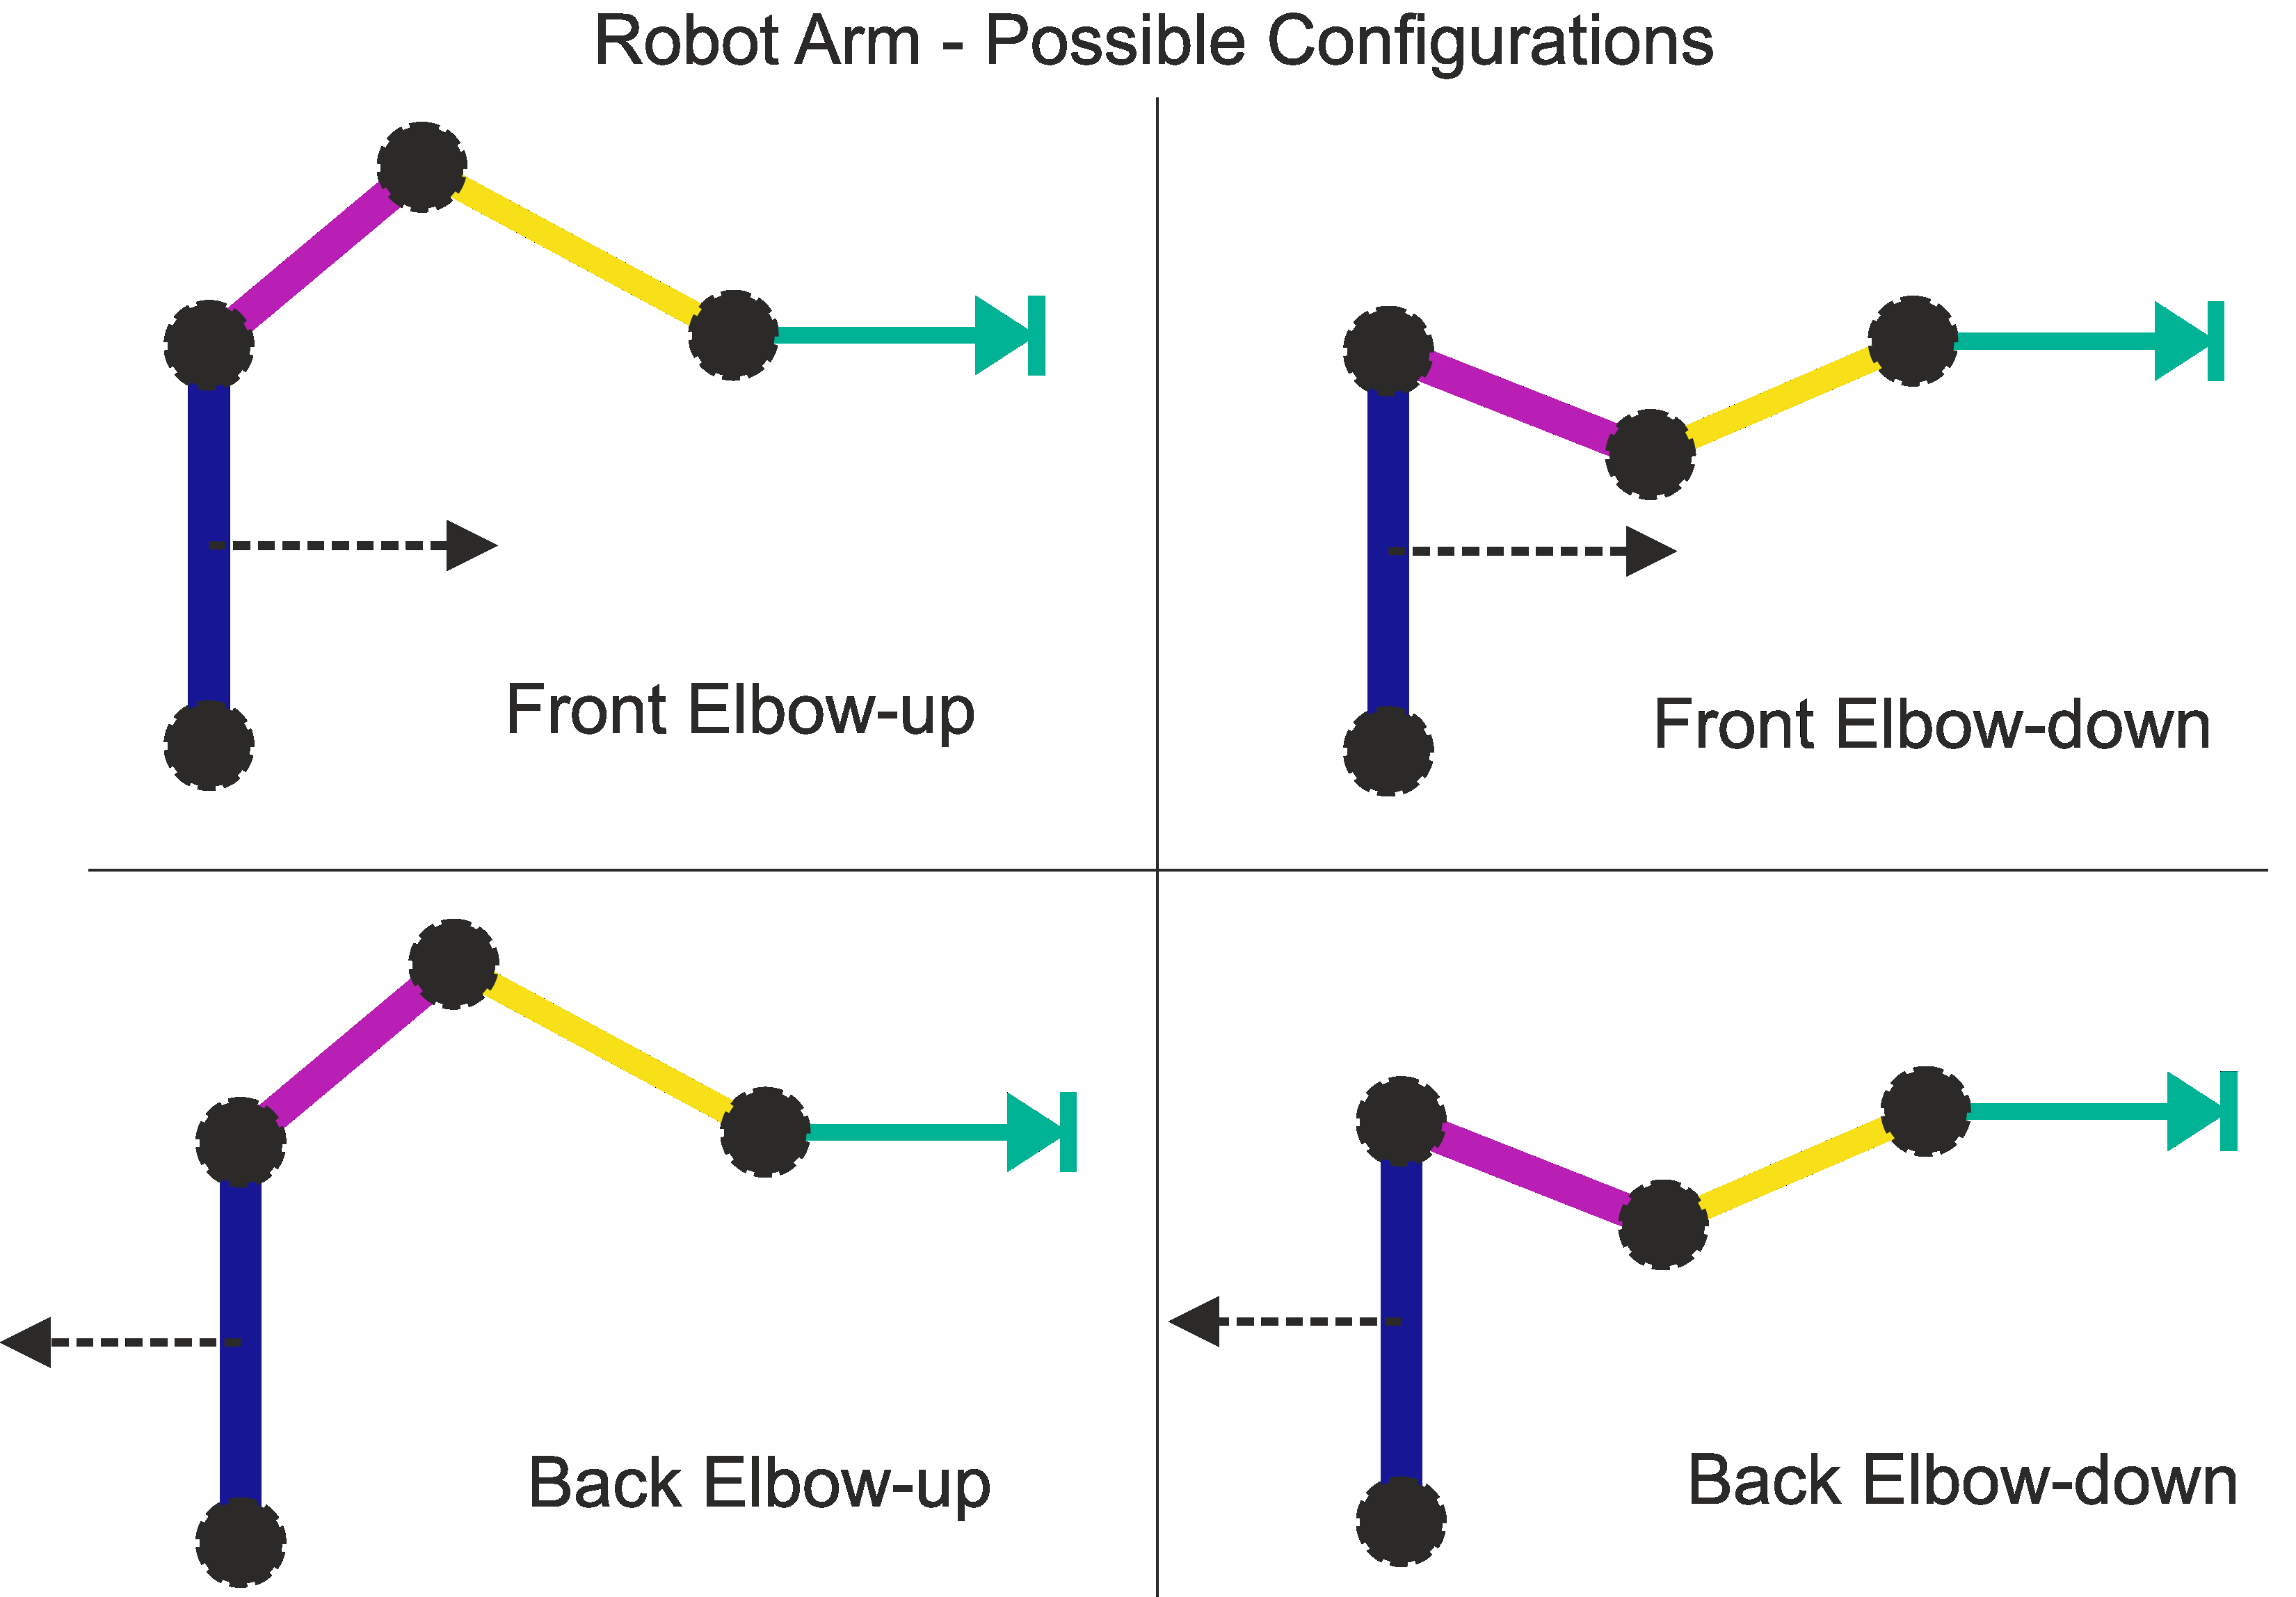

Some solutions can be eliminated using Joint Angle limits, but the problem is still a complex one when 3 more joints are added in at the wrist.

Therefore, in the interest of practicality, we typically break this down into smaller problems. We also must give the following information to solve the inverse kinematics problem, using this approach:

- The (x,y,z) coordinates of the end effector, which is a 3x1 matrix and,

- The Rotation Matrix of the end effector, which defines the orientation from which the tool is approaching the workpiece. This is a 3x3 matrix

- Length of the tool

If the length of the tool and its approach orientation is known, then we can follow the steps described below (Geometric Approach) to calculate the Inverse Kinematics solution for the Joint Angles.

## 1. Calculation of Wrist Joint

*Calculate the position (x,y,z) of the wrist joint by working backwards from supplied Translational and Rotational matrices, using the known length of the tool.*  

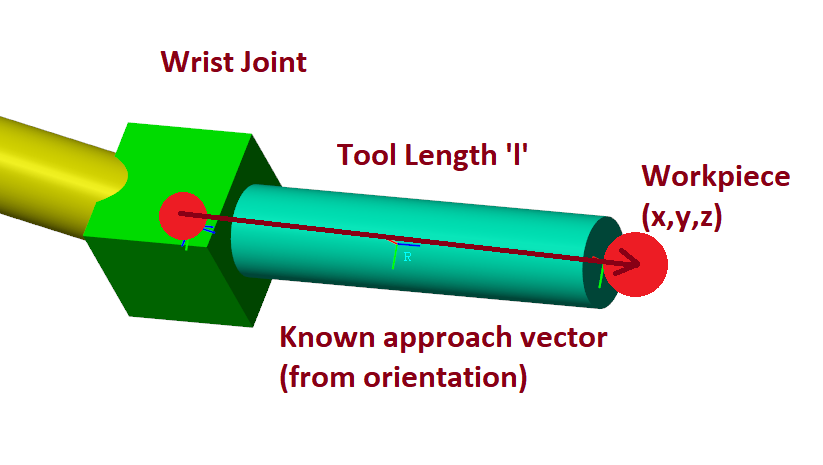

If the position of the workpiece (x,y,z) is known, and the approach vector is known (derived from the supplied matrix 'R'), then calculating the position of the wrist joint is relatively straightforward. 

For example:

% x,y,z coordinates of end-point
p = [0.5 1.5 1] 

% approach vector (in global coordinate frame)
R = [ 0.8365 -0.4830 0.2588;...
      0.4250  0.8700 0.2500;...
     -0.3459 -0.0991 0.9330] 

% length of tool in meters
l = 0.1 

% z is the direction of axis Z of frame 6 w.r.t base frame
z = [R(1,1) R(2,2) R(3,3)]

%finding wrist center from given end effector position and z6
xc = p(1) - l*z(1);
yc = p(2) - l*z(2);
zc = p(3) - l*z(3);

% wrist center
wc = [xc yc zc]

## **2. Calculation of Joint Angle 1**

Now we can find out joint angle Theta1 easily by calculating the required rotation. 

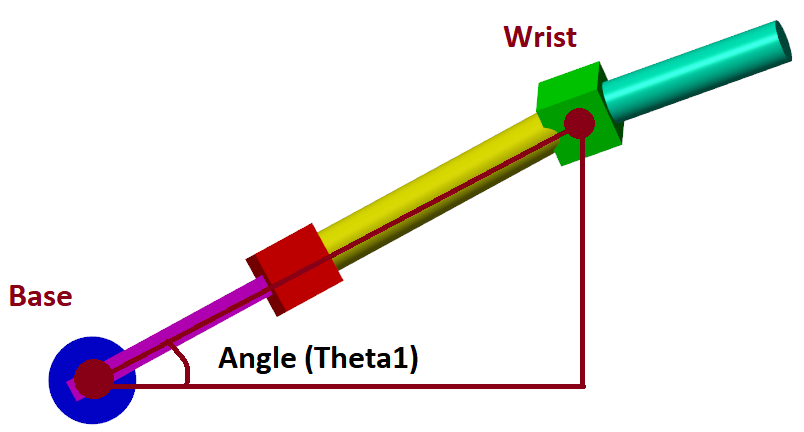

theta1 = rad2deg(atan2(xc,yc))         % degrees

Another solution for the 'reverse' or 'backward-bending' position is also possible. For this example, we will consider only the 'forward-facing' solutions, but the reverse angles are also valid solutions and important for many industrial applications.

theta1_alt = rad2deg(atan2(xc,yc))-180 % degrees

## 3. Calculation of Joint Angles 2 & 3

Then, calculating joint angles '2' & '3' is reduced to a much simpler 2DoF problem, as shown below.

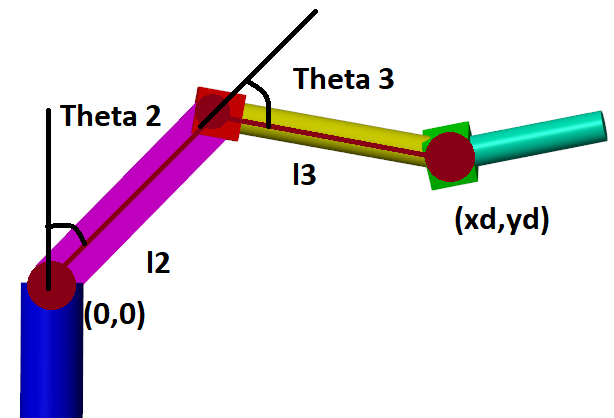

Suppose we are solving for Theta2 and Theta3. Then:

% from above
xd = sqrt(xc^2 + yc^2)
yd = zc- 0.5  % height of first link
l2 = 1        % length l2 (m)
l3 = 0.75     % l3 (m)

% distance between base and wrist
d = sqrt(xd^2 + yd^2)

% Calculate the forearm link angle
cosb = (l2^2 + l3^2 - d^2)/(2*l2*l3);
sinb = sqrt(1 - cosb.^2);
b = rad2deg(atan2(sinb, cosb))
theta3 = 180-b

% Calculate the bicep link angle
b1 = rad2deg(atan(yd/xd));
b2 = rad2deg(atan2( (l3*sind(theta3)), (l2+l3*cosd(theta3))));
theta2 = 90-b1-b2

Robotics can be confusing with different angle and joint conventions. So it's best to quickly check the calculations once.

x_error = l2*sind(theta2) + l3*sind(theta2+theta3) - xd
y_error = l2*cosd(theta2) + l3*cosd(theta2+theta3) - yd

Perfect!

But remember, even here, there are two possible solutions - 'Elbow Up' and 'Elbow Down.' We can select either, depending on the configuration of the robot.

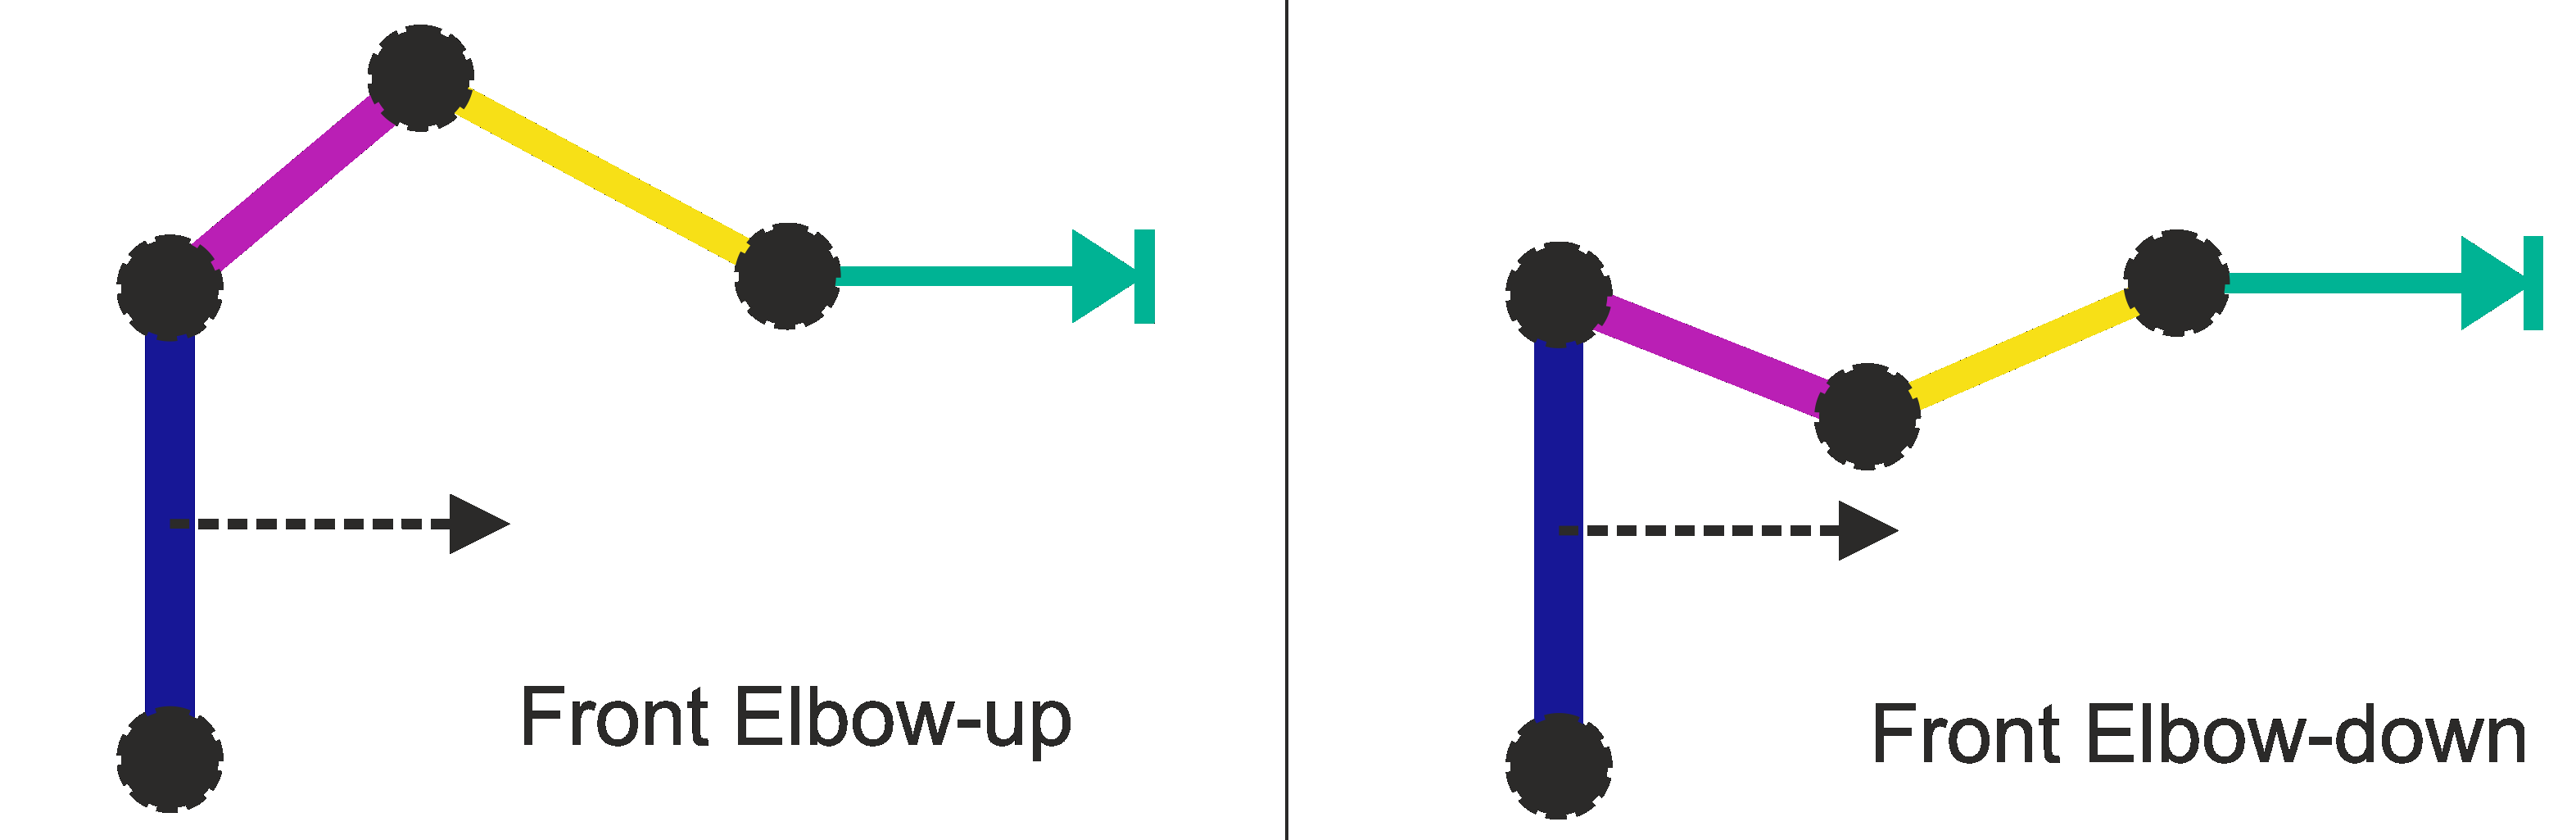

% elbow down solution
theta3_alt = -theta3
b1 = rad2deg(atan(yd/xd));
b2 = rad2deg(atan2( (l3*sind(theta3_alt)), (l2+l3*cosd(theta3_alt))));
theta2_alt = 90-b1-b2

x_error = l2*sind(theta2_alt) + l3*sind(theta2_alt+theta3_alt) - xd
y_error = l2*cosd(theta2_alt) + l3*cosd(theta2_alt+theta3_alt) - yd

And we can see, that works as well.

## 4. Work out the last 3 joint angles

Despite the apparent complexity of the wrist joint, this is actually the easiest step. We need not do this here in detail, but here are the general steps: 

- Once Theta1, Theta2 and Theta3 have been calculated, use the Forward Kinematics to work out $R_3^0$

- As $R_6^0 =R_3^0 R_6^3$, we can use this to calculate the wrist position $R_6^3$ as $R_6^3 ={\left(R_3^0 \right)}^{-1} R_6^0$

- Now simply use Euler Angles to find the last 3 joint values to satisfy$R_6^3$

As we saw in the first script about Rotation Matrices,

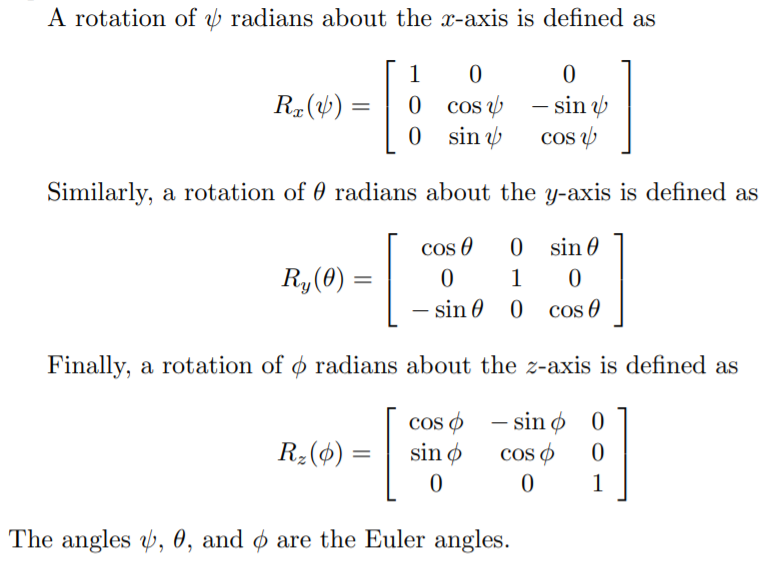

Therefore,

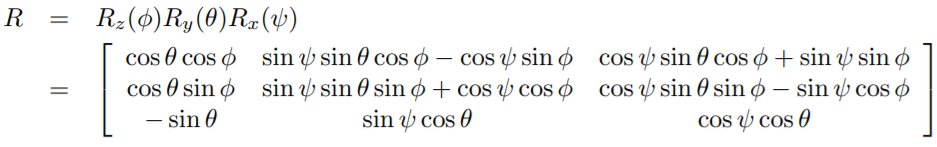

We can solve backwards from this systematically to determine the values of $\theta ,\phi \;$and $\psi$.

How?

If you notice, $R_{3,1} \;=\;-\sin \left(\theta \right)$

Therefore, we can get 2 values of $\theta$ from here.

Similarly, we can use the other parts of the matrix to generate solutions for $\phi \;$and $\psi$.

For example, suppose: 

R = [0.3536 -0.6124  0.7071;...
     0.9268  0.1268 -0.3536;...
    -0.1268  0.7803  0.6124]

theta1 = rad2deg(-asin(R(3,1)))
theta2 = 180-theta1

And so on...

Note that there are always multiple possible solutions for these angles. Therefore the physical limits on the Robot can be used to discard the unrealistic solutions and keep only the workable joint angles.